# Mapping

Use the idea behind the line tracing

Visit: https://es.wikipedia.org/wiki/Algoritmo_de_Bresenham

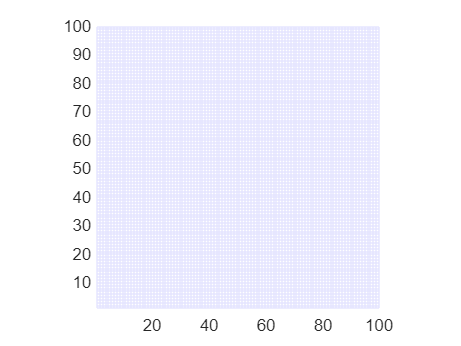

A=ones(100,100);
s=pcolor (A);
colormap(gray(2))
s.EdgeColor = [0.9 0.9 1];
axis square

[x, y]=bresenham(0 ,0,10,40); % Can't catch both values in one variable
l_xy = [x y]

l_xy =      0     0
     0     1
     0     2
     1     3
     1     4
     1     5
     1     6
     2     7
     2     8
     2     9


L=length(x);
P_w=transl(10,10,0)*[l_xy zeros(1,L)' ones(1,L)']'

P_w =     10    10    10    11    11    11    11    12    12    12    12    13    13    13    13    14    14    14    14    15    15    15    15    16    16    16    16    17    17    17    17    18    18    18    18    19    19    19    19    20    20
    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


for i=1:L
    A(P_w(1,i),P_w(2,i))=0;
end

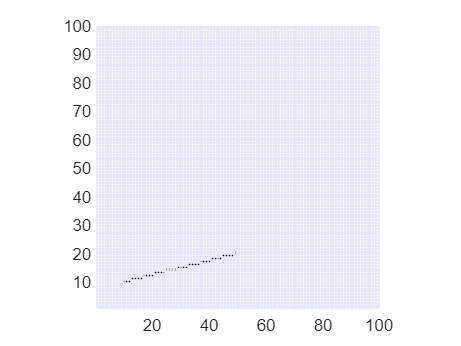

s=pcolor (A);
s.EdgeColor = [0.9 0.9 1];
colormap(gray(2))
axis square

Animation

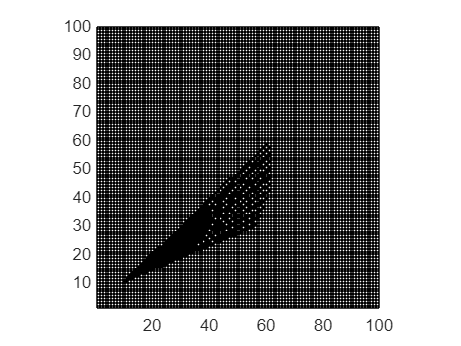


A=ones(100,100);
Laser_data=[10 40 0 1]';
for j=1:20
    P_w=transl(50,20,0)*trotz(j*pi/80)*Laser_data;% Laser wordl
    [x, y] = bresenham(10, 10,round(P_w(1)), round(P_w(2)) );
    l_xy = [x y];
    L=length(l_xy);
    for i=1:L
        A(l_xy(i,1),l_xy(i,2))=0;
    end
    pcolor (A)
    colormap(gray(2))
    axis square
    pause(0.9)
    drawnow
end